clc;
clearvars;

**Input variables:**

W0 = 100;                               % Mass flow                               (kg/s)
R = 287.05;                             % Gas constant                            (J/kgK)
IntakeP_loss = 0;                       % Intake pressure loss                    (%)
ExhaustP_loss = 0;                      % Exhaust pressure loss                   (kPa)
JetpipeP_loss = 0;                      % Jet pipe pressure loss                  (%)
CD = 1;                                 % Coefficient of discharge                (%)
CX = 1;                                 % Coefficient of thrust                   (%)
Mech_Eff = 0.86;                        % Mechanical efficiency                   (%)

**Input height: calculates temperature and pressure**

h = linspace(0,15000,100);

Pb = 101.325;
Tb = 288.2;
hb = 0;
Lb = 0.0065;
g = 9.80665;
Mol = 0.0289644;
R1 = 8.3144598;
P0 = Pb * ((Tb - (h - hb) * Lb)/Tb).^((g * Mol)/(R1 * Lb));

T0 = Tb - (h * Lb);

**Compressor:**

y_c = 1.4;                              % Heat capacity ratio compressor          (-)
CompressorIsent_Eff = 0.8;              % Compressor isentropic efficiency        (%)
ETAP2 = 0;                              % Compressor polytopic efficiency         (%)
CP_compressor = 1.005;                  % Specific heat compressor                (kJ/kg)
P3Q2 = 8;                               % Pressure ratio compressor               (-)
CompressorP_loss = 0;                   % Compressor pressure loss                (%

**Combustor:**

CombustionP_loss = 0;                   % Combustion pressure loss                (kPa)
CombustionIsent_Eff = 0.95;             % Combustion efficiency                   (%)

**Turbine:**

y_t = 1/3;                              % Heat capcity ratio turbine              (-)
TurbineIsent_Eff = 0.85;                % Turbine isentropic efficiency           (%)
TurbinePoly_Eff = 0;                    % Turbine polytropical eff.               (%)
CP_turbine = 1.150;                     % Specific heat turbine                   (kJ/kg)

**Temperatures:**

T41 = 1600;                             % Temperature after combustion            (K)

**Bleed:**

Bleed1 = 0.01;                          % Bleed air from compressor to outlet     (%)
Bleed2 = 0.08;                          % Bleed air from compressor to LPT        (%)
Bleed3 = 0.075;                         % Bleed air from compressor to HPT        (%)
Bleed4 = 0.047;                         % Bleed air to first LPT nozzle           (%)
Bleed5 = 0.033;                         % Bleed air to second LPT nozzle          (%)

**Fuel:**

LHV = 43*10^6;                          % Calorific value fuel                  (kJ/kg)

**Stations: **

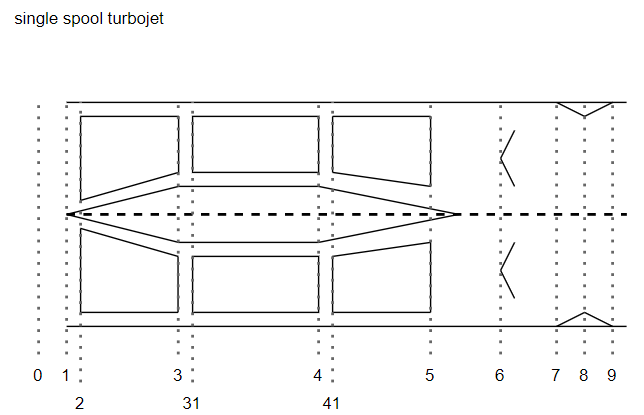

**Station 0: atmosperic calculations**

T0;
P0;
W0;

**Station 1: Intake**

T1 = T0;
P1 = P0;
W1 = W0;

**Station 2: Compressor inlet**

T2 = T1;
P2 = P1 * (1 - IntakeP_loss); 
W2 = W1;

**Station 3 :Compressor calculations: **

% ETA2 = (P3Q2^((y_c-1)/y_c)-1)/(P3Q2^((y_c-1)/(y_c*ETAP2))-1);     % Converts polytropic to isentropic                                

T3 = T2/CompressorIsent_Eff * (P3Q2^((y_c-1)/y_c)-1) + T2;
P3 = P3Q2 * P2;
W3 = W2 - (W0 * Bleed1) - (W0 * CompressorP_loss);                                                             

Tbleed = (T3 + T1)/2; % moet nog verwerkt worden in totale temperatuur
PW3 = W0 * (CP_compressor) * (T3 - T1)+ 1.5 * CP_compressor * (Tbleed - T0);                               % No Tbleed

**Station 31: Combuster inlet **

T31 = T3;
P31 = P3 * (1- CombustionP_loss);
W31 = W3 - (W0 * Bleed2) - (W0 * Bleed3);

**Station 4: Combustor outlet: **

P4 = P31 * (1 - CombustionP_loss);
T41;
FAR1 = 0.10118 + 2.00376E-05 * (700 - T31);
FAR2 = 3.7078E-03 - 5.2368E-06 * (700 - T31) - 5.2632E-06 * T41;
FAR3 = 8.889E-08 * abs(T41 - 950);
FAR = (FAR1 - sqrt(FAR1.^2 + FAR2) - FAR3)/CombustionIsent_Eff;
WF = FAR * (W31 + W0 * Bleed3);                       % WF = Q/LHV (alternative formula)
W41 = W31 + (W0 * Bleed3) + WF;

**Station 41: Turbine inlet calculations**

W4 = WF + W31;
T4 = (W41 * CP_turbine * T41)-((Bleed3 * W0) * CP_compressor * T3)/(W41 * CP_turbine);
P41 = P4;

**Station 5: Turbine outlet calculations:**

WC = W3 * CP_compressor * (T31 - T2);
T5 = T41 - (WC/(W4 * CP_turbine));
Expansion_ratio = nthroot((1-(T41-T5)/(TurbineIsent_Eff*T41)),(-1/4));
P5 = P41/Expansion_ratio;
W5 = W41 + (Bleed5 * W0) + (Bleed1 * W0);

**Station 6: Afterburner calculations **

T6 = T5;
P6 = P5;
W6 = W5 + (W0 * Bleed1) + (W0 * Bleed5);

**Station 7: Propelling nozzle inlet**

T7 = T6;
P7 = P6 * (1-JetpipeP_loss);
W7 = W6;

**Station 8: Propelling nozzle throat:**

T8 = T6;                                                
P8 = P6;
W8 = W6;

Ps = P6/(1 + (y_c - 1)/2)^(y_c/(y_c-1));
Ts = T6/(1 + (y_c - 1)/2);
VN = sqrt(y_t * R * Ts);                                % Nett velocity                                             

rho = (Ps.*1000)./(Ts.*R);
ANeffective = W0./(VN.* rho);   

**Sation 9: Exhaust calculations: **

T9 = T8;
P9 = P8.*Ps;
W9 = W8;

**Final calculations:**

Fn = (W0 + WF).* VN + ANeffective.* (Ps - P1).* 1000;
SFN = Fn/100;                                           % Specific thrust
SFC = (WF./Fn).*1000000;                                % SFC = WF * 3600/FN not corresponding                   
SPW = Fn/W0;                                            % Specific power 
ETATH = 100.*(3600./(SFC.*(LHV/10^5)));                 % Thermal efficiency

**Plots:**

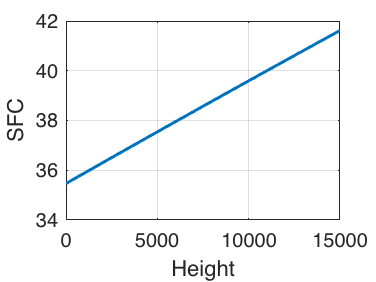

s1 = plot (h, SFC,LineWidth=1.5);
xlabel('Height');
ylabel('SFC');
grid on;

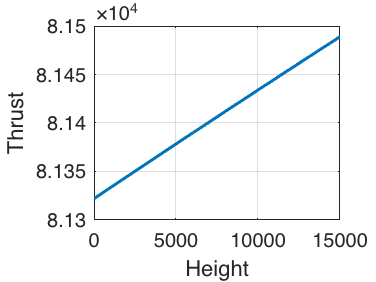


s2 = plot (h, Fn,LineWidth=1.5);
xlabel('Height');
ylabel('Thrust')
grid on;

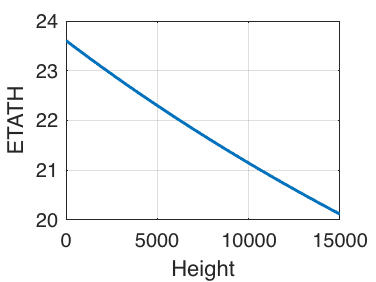


s3 = plot (h, ETATH,LineWidth=1.5);
xlabel('Height');
ylabel('ETATH')
grid on;

Un used formulas:

% Q = 1000 * sqrt( 2 * y_t/((y_t-1) * R) * ((1+0.2*1^2)^3.5)^(-2/y_t) * (1 - ((1+0.2*1^2)^3.5)^ ((1 - y_t)/y_t)))
% Q = W31 * CP_turbine * (T4 - T31);
% DT = T4 - T1;
% DH = DT * W31 * CP_turbine;
% P4_5 = P3_5* (1- (1-(T3_5/T3))/ETHA_turb).^(y_t/(y_t- 1));
% P4_5 = PAMB/(1-ExhaustP_loss);
% E415 = (1 - P415Q416^(- ((y_t-1)/y_t) * TurbineIsent_Eff))/(1 - P415Q416^(-(y_t-1)/y_t));
% T416 = E415 * T4 * (1 - P415Q416^(-((y_t-1)/y_t)));
% PW415 = W415 * CP_turbine * (T4 - T416);                
% WRTP4 = W3_5 * sqrt(T3_5)/P3_5;
% WRTP41 = W3_5 * sqrt(T41)/P3_5;
% T5 = T4_5 - (PW2/(W3_5 * CP_turbine))
% ANeffective = (W6 * sqrt(T5))/(Q * P6);
% ANgeometric = ANeffective/CD;
% FD = 100 * V1;                                          % Momentum drag
% FN = FG * CX - FD;                                    % Net thrust
% PW = PW415 - PW2/Mech_Eff 